%% clear cache
clc;
clear variables;

%% set AudioFileManipulator class parameters
input_file_path = "vaiueo2d.wav";
output_file_path = "D:/名城大学/研究室/演習/data/LinearPredictiveCoding/synthesized_signal_by_LPCVocoder.wav";

%% generate AudioFileManipulator instance and confirm properties
audio_file_manipulator = AudioFileManipulator(input_file_path, output_file_path);
audio_file_manipulator.load_properties();
audio_file_manipulator.display_properties();

--------------------------------------------
---------- Audio File Manipulator ----------
input_file_path : vaiueo2d.wav
output_file_path : D:/名城大学/研究室/演習/data/LinearPredictiveCoding/synthesized_signal_by_LPCVocoder.wav
signal shape : (17500, 1)
sample_rate: 22050 [Hz]
             Filename: 'D:\名城大学\研究室\演習\MatlabPractice\SourceCode\Analysis\STRAIGHT\STRAIGHTV40_007b\vaiueo2d.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 22050
         TotalSamples: 17500
             Duration: 0.7937
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16

--------------------------------------------



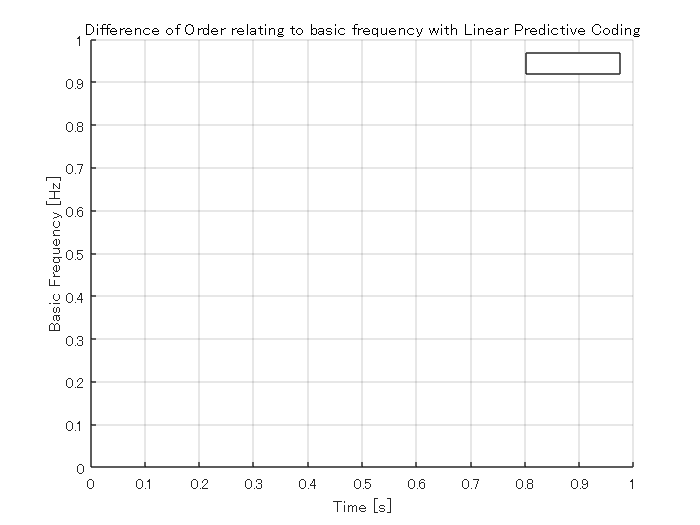

hold on;
grid on;
title("Difference of Order relating to basic frequency with Linear Predictive Coding");
xlabel("Time [s]");
ylabel("Basic Frequency [Hz]");
legend;

----------------------------------------------
-- Linear Predictive Coding Pitch Extractor --
signal size : (17500, 1)
window_mode : hamming
sample_rate : 22050 [Hz]
order : 5
voicing_threshold : 0.010000
frame_length : 706 [sample]
hop_length : 176 [sample]
basic_frequencies size : (99, 1)
basic_periods size : (99, 1)
----------------------------------------------

----------------------------------------------
-- Linear Predictive Coding Pitch Extractor --
signal size : (17500, 1)
window_mode : hamming
sample_rate : 22050 [Hz]
order : 10
voicing_threshold : 0.010000
frame_length : 706 [sample]
hop_length : 176 [sample]
basic_frequencies size : (99, 1)
basic_periods size : (99, 1)
----------------------------------------------

----------------------------------------------
-- Linear Predictive Coding Pitch Extractor --
signal size : (17500, 1)
window_mode : hamming
sample_rate : 22050 [Hz]
order : 20
voicing_threshold : 0.010000
frame_length : 706 [sample]
hop_length : 176 [sample]
b

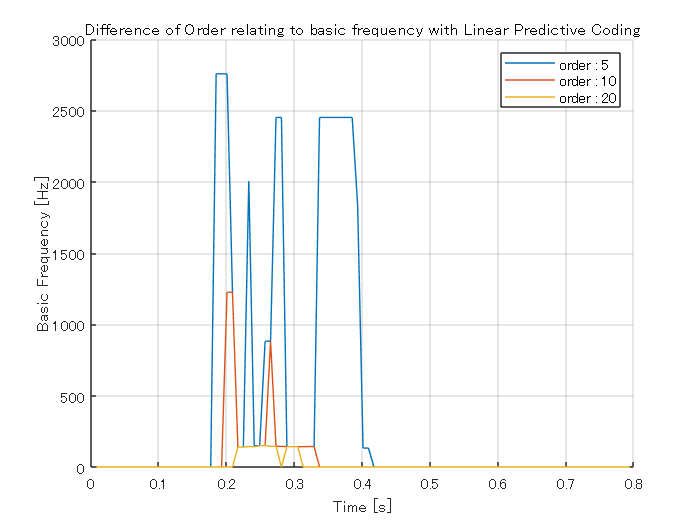

%% generate LPCVocoder instance
order_list = [5, 10, 20];
for order_index = 1 : length(order_list)
    linear_predictive_coding_pitch_extractor = LinearPredictiveCodingPitchExtractor(audio_file_manipulator.signal, audio_file_manipulator.information.SampleRate, "hamming", order_list(order_index), 0.01);
    linear_predictive_coding_pitch_extractor.display_properties();
    plot((1 : length(linear_predictive_coding_pitch_extractor.basic_frequencies)) / length(linear_predictive_coding_pitch_extractor.basic_frequencies) * length(audio_file_manipulator.signal) / audio_file_manipulator.information.SampleRate, linear_predictive_coding_pitch_extractor.basic_frequencies, "DisplayName", "order : " + int2str(order_list(order_index)));
end

saveas(gcf, "D:/名城大学/研究室/演習/data/LinearPredictiveCoding/Difference_of_Order_relating_to_basic_frequency.png");